# **Workshop** - 3-link Robot Model Parameters

*This script defines all the parameters needed to run the workshop_3link_robot_integration.slx model.*

### Define some Material and Environment parameters

We'll represent each link in the pendulum as a rectangular prism(or BRICK).  So one of the first things we'll need are the inertia properties of the 2 links. We'll assume that each link has the same density.

robo_params.density = 1000;     % (kg/m3)
robo_params.g       = 9.80665;  % (m/sec^2)

### Define some Geometry and Mass parameters for Link 1

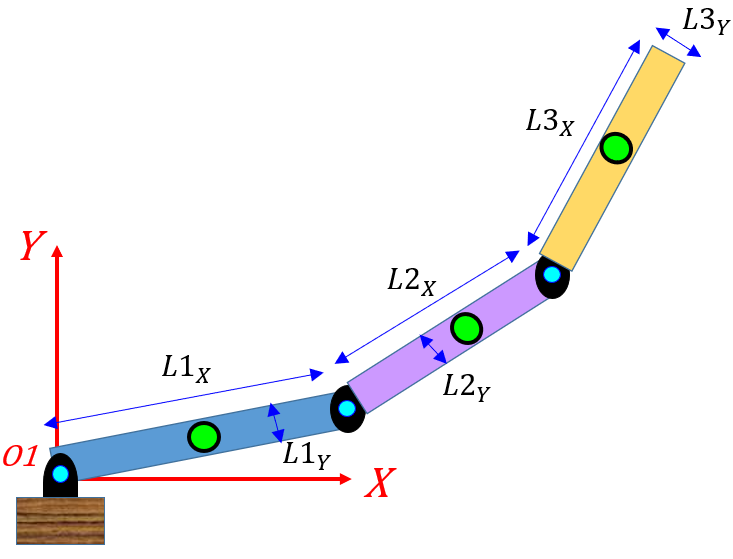

robo_params.L1x     = 1.000; % (m)
robo_params.L1y     = 0.050; % (m)
robo_params.L1z     = 0.005; % (m)
robo_params.L1xyz   = [robo_params.L1x,  robo_params.L1y,   robo_params.L1z];
robo_params.volume1 = robo_params.L1x * robo_params.L1y * robo_params.L1z;   % (m^3)
robo_params.mass1   = robo_params.density * robo_params.volume1;             % (kg)

### Define some Geometry and Mass parameters for Link 2

robo_params.L2x     = 0.500; % (m)
robo_params.L2y     = 0.050; % (m)
robo_params.L2z     = 0.005; % (m)
robo_params.L2xyz   = [robo_params.L2x,  robo_params.L2y,   robo_params.L2z];
robo_params.volume2 = robo_params.L2x * robo_params.L2y * robo_params.L2z; % (m^3)
robo_params.mass2   = robo_params.density * robo_params.volume2;           % (kg)

### Define some Geometry and Mass parameters for Link 3

robo_params.L3x     = 0.250; % (m)
robo_params.L3y     = 0.050; % (m)
robo_params.L3z     = 0.005; % (m)
robo_params.L3xyz   = [robo_params.L3x,  robo_params.L3y,   robo_params.L3z];
robo_params.volume3 = robo_params.L3x * robo_params.L3y * robo_params.L3z; % (m^3)
robo_params.mass3   = robo_params.density * robo_params.volume3;           % (kg)

### Define some damping at each revolute joint

We'll assume that each revolute joint applies viscous damping to the rigid bodies, ie: $\tau_{damping} = b \thinspace \dot{\theta}$.   

robo_params.b1_damp = 0.005; %0.1 (N.m/(rad/sec));
robo_params.b2_damp = 0.005; %0.1 (N.m/(rad/sec));
robo_params.b3_damp = 0.005; %0.1 (N.m/(rad/sec));

### Define the INITIAL Conditions

Recall the angular degrees of freedom of the machine:

 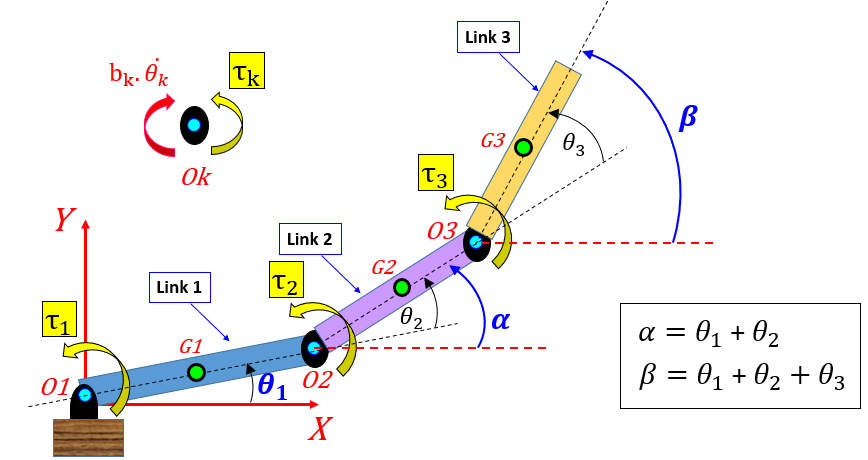

Here are the system INITIAL conditions:

- $\left\lbrack \theta_1 \left(0\right),\;\;\;\theta_2 \left(0\right)\;,\;\theta_3 \left(0\right)\right\rbrack =\left\lbrack 0\ldotp 455\ldotp \ldotp \ldotp ,,\;-1\ldotp 009\ldotp \ldotp \ldotp ,\;-0\ldotp 231\ldotp \ldotp \ldotp \;\right\rbrack$     `(rad)`

- $\left\lbrack {\dot{\theta} }_1 \left(0\right),\;{\dot{\theta} }_2 \left(0\right),\;{\dot{\theta} }_3 \left(0\right)\right\rbrack \;\;=\left\lbrack 0,\;0,\;0\right\rbrack$            (`rad/sec)`

- $\alpha(0) = \theta_1(0) + \theta_2(0)$    `              (rad)`

- $\dot{\alpha}(0) = \dot{\theta}_1(0)  + \dot{\theta}_2(0) $                                (`rad/sec)`

- $\beta(0) = \theta_1(0) + \theta_2(0) + \theta_3(0)$    `        (rad)`

- $\dot{\beta}(0) = \dot{\theta}_1(0)  + \dot{\theta}_2(0)  + \dot{\theta}_3(0) $                   (`rad/sec)`

IC.theta1_0     = 0.455476729513513;                                        % (rad)
IC.theta2_0     = -1.00963484107972;                                        % (rad)
IC.theta3_0     = -0.231240051831237;                                       % (rad)
IC.theta1_dot_0 = 0;                                                        % (rad/sec)
IC.theta2_dot_0 = 0;                                                        % (rad/sec)
IC.theta3_dot_0 = 0;                                                        % (rad/sec)
IC.alpha_0      = IC.theta1_0     +  IC.theta2_0;                           % (rad)
IC.beta_0       = IC.theta1_0     +  IC.theta2_0     +  IC.theta3_0;        % (rad)
IC.alpha_dot_0  = IC.theta1_dot_0 +  IC.theta2_dot_0;                       % (rad/sec)
IC.beta_dot_0   = IC.theta1_dot_0 +  IC.theta2_dot_0 + IC.theta3_dot_0;     % (rad/sec)

## Specify the desired End Effector position

my_data_table = readtable('TRAJECTORY_DATA_3LINK.xlsx', 'Sheet', 'T_TH_XY');
    
the_EE.xE  = my_data_table.XE;
the_EE.yE  = my_data_table.YE;
the_EE.zE  = zeros(size(the_EE.xE));
    
[~, tmp_iA] = uniquetol([the_EE.xE, the_EE.yE, the_EE.zE], 0.0001, "ByRows", true);
ind = sort(tmp_iA);
    
the_EE.XYZ_spline =  [the_EE.xE(ind), the_EE.yE(ind), the_EE.zE(ind)];

## Start a new Simscape™ Multibody™ model 

Let's open a blank Simscape Multibody model template with commonly used blocks 

model = smnew('workshop_3link_robot_integration_blank');
activeConfigObj = getActiveConfigSet(model);
tStop=30;
set_param(activeConfigObj,'StopTime','tStop');